# MATLAB Basic-2: 

## For Loop

for loop repeats for a specified number of times

Syntax:

for index=range of values

   <statements...>

end

Example-1: Write a program to calculate factorial of  n. Take n=8.

n=8;
fact=1;
for i=1:n
    fact=fact*i;
end
fprintf('Factorial of number %d is %d\n',n,fact);

Factorial of number 8 is 40320


Example-2: Write a program to display first n terms of fibonacci series. Take n=8

n=8;
fibo=[1 1]; % Implies fibo(1)=1 & fibo(2)=1 ; These are first two terms of Fibonacci series
for i=3:n
    fibo(i)=fibo(i-1)+fibo(i-2);
end
disp(fibo)

     1     1     2     3     5     8    13    21



## While Loop

while loop to repeat when condition is true

Syntax

while condition

      statements

end

Example-3: Write a program to display fibonacci series such that last term is below x=100

x=100;
i=2;
fibo=[1 1];
fibo_LastTerm=1;
while fibo_LastTerm<x
    i=i+1;
     fibo(i)=fibo(i-1)+fibo(i-2);
     fibo_LastTerm=fibo(i);
end
fibo(1:i-1)

ans =      1     1     2     3     5     8    13    21    34    55    89


## Conditional Statements:

## if, elseif, else

Execute statements if condition is true

Syntax:

`if condition`

`    statements`

`elseif condition`

`    statements`

`else`

`    statements`

`end`

## `Example:Find out all the prime numbers between m=10 and n=100 `

m=10;
n=100;
k=0;
prime=[];

for i=m:n
    x=ceil(sqrt(i));
    j=2;
    while j<x
          if rem(i,j)==0
             j=x+5;
          else
             j=j+1;
          end
    end
    if j==x
       k=k+1;
       prime(k)=i;
    end
end
prime

prime =     11    13    17    19    23    25    29    31    37    41    43    47    49    53    59    61    67    71    73    79    83    89    97


## Tutorial-2

## Problem-1: 2-D temperature field data in a metal plate of 10cm by 10cm, is to be stored for the discrete grid points as shown in the figure. It is known that continuous temperature field is given as $T=x^2 +2xy$,  Also draw the contour plot of the temperature field based on the grid points data stored.

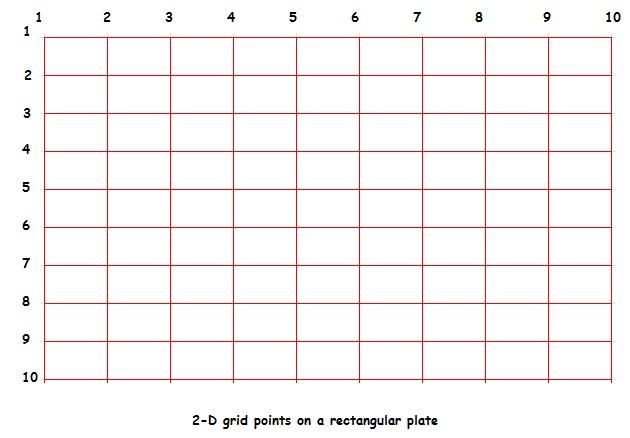

## Solution:

Plate dimension

lx=10; % length in cm unit
ly=10; % width in cm unit

creating grid points along x and y axis

m=10;% number of grid points along x
n=10; % number of grid points along y
x=linspace(0,lx,m);
delx=x(2)-x(1); %spacing between two grid points along x axis in cm
y=linspace(0,ly,n);
dely=y(2)-y(1); %spacing between two grid points along y axis in cm

Assign temperature to this grid points using the field relation  $T=x^2 +2\text{xy}$, 

for i=1:m
    for j=1:n
        T(j,i)=x(i)^2+2*x(i)*y(j);
    end
end

Create Mesh Grid

[X,Y]=meshgrid(x,y);

Contour Plot

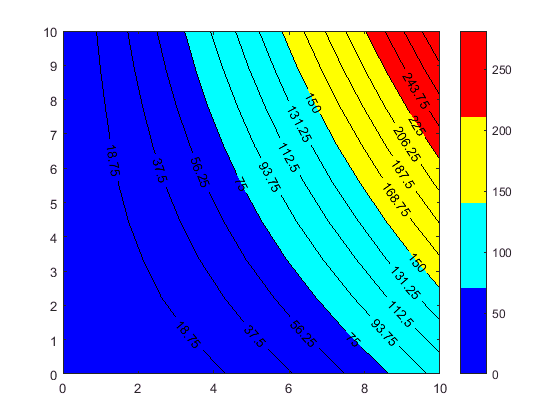

contourf(X,Y,T,15,'ShowText','on');
%c.LineWidth=3;
colormap(jet(4)); 
colorbar;

## Problem-2: 

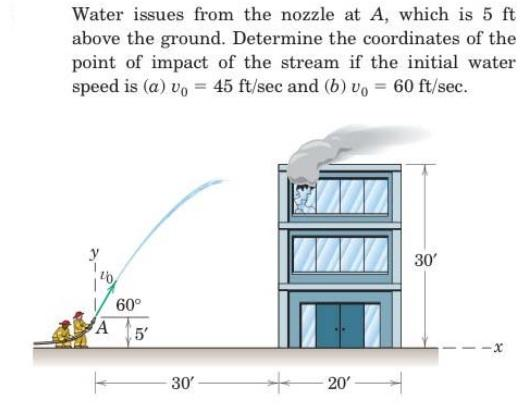

We also have to find out the path of the projectile motion as well.

## Solution:

Initial Condition given: At time t=0, position of the water jet x0=0 ft and y0=5 ft

x0=0;
y0=5;

Target of the water jet at the building roof is at the coordinate xT=30ft , we have to find yT . It is given height of the building H=30ft and width W=20ft

xT=30;
H=30;
W=20;

Initial Condition given: At time t=0, velocity of water jet v0=45ft/s at an angle ${\theta =60}^o$ with x axis

theta=60; % initial velocity at an agle with x axis
v0(1)=45; % Case-1: Initial velocity magnitude in ft/s
v0(2)=30; % Case-2: Initial velocity magnitude in ft/s

Initial x and y component of velocity are $v0x=v0cos\theta$ & $v0y=v0sin\theta$ respectively.

%Case-1:
v0x(1)=v0(1)*cos(theta*pi/180);
v0y(1)=v0(1)*sin(theta*pi/180);
%Case-2:
v0x(2)=v0(2)*cos(theta*pi/180);
v0y(2)=v0(2)*sin(theta*pi/180);

Assuming motion of the water jet projectile is governed by the gravitational foece field only.

Therefore, acceleration along x direction ax=0 and acceleration in the y direction ay=-g$=−32\ldotp 2\frac{ft}{s^2 }$

Therefore, governing differential equations are, $\frac{d^2 x}{{dt}^2 }$=0 & $\frac{d^2 y}{{\text{dt}}^2 }=−g$ Initial conditions are At t=0, $\frac{dx}{dt}$=v0x, $\frac{\text{d}y}{\text{dt}}$=v0y, x=x0,y=y0;

Solving this governing differential equations with initial condition gives


$$\begin{array}{l}
x=x0+v0x∗t\\
y=y0+v0y∗t−\frac{1}{2}g∗t^2 
\end{array}$$


## Case-1


g=32.2; % acceleration due to gravity in ft/s^2
t=0;
k1=1;
x1_track=0; %tracking x coordinate at each time step
y1_track=1; % Some positive value initialized 
x1=[];%initialize x coordinates
y1=[]; %initialize y coordinates
while (x1_track<xT && y1_track>0) || (y1_track>H && x1_track>xT) || (y1_track<H && x1_track>xT+W && y1_track>0)
    
    x1(k1)=x0+v0x(1)*t; %x motion equation
    x1_track=x1(k1);
    y1(k1)=y0+v0y(1)*t-0.5*g*t^2;   % y-motion equation
    y1_track=y1(k1);
    t=t+0.001;% time steps in sec
    k1=k1+1;
end

Now we can find the height where water jet will strike the building. That will be yT 

X1=x1([1:k1-2]); % correction of the x dataset to eliminate values more than target x
Y1=y1([1:k1-2]); % correction of the y dataset to eliminate values corresponding to x more than target x
yT1=Y1(end) % Height where jet will strike.

yT1 = 28.3406

## Case-2:

g=32.2; % acceleration due to gravity in ft/s^2
t=0;
k2=1;
x2_track=0; %tracking x coordinate at each time step
y2_track=1; % Some positive value initialized
x2=[];%initialize x coordinates
y2=[]; %initialize y coordinates
while (x2_track<xT && y2_track>0) || (y2_track>H && x2_track>xT) || (y2_track<H && x2_track>xT+W && y2_track>0)
    
    x2(k2)=x0+v0x(2)*t; %x motion equation
    x2_track=x2(k2);
    y2(k2)=y0+v0y(2)*t-0.5*g*t^2;
    y2_track=y2(k2);% y-motion equation
    t=t+0.001;% time steps in sec
    k2=k2+1;
end

Now we can find the height where water jet will strike the building. That will be yT 

X2=x2([1:k2-2]); % correction of the x dataset to eliminate values more than target x
Y2=y2([1:k2-2]); % correction of the y dataset to eliminate values corresponding to x more than target x
yT2=Y2(end) % Height where jet will strike.

yT2 = 0.0144

## Visualization of the trajectory.


plot(X1,Y1,X2,Y2,'LineWidth',2);
grid on;
set(gca,'FontSize',12,'FontName','Times');
xlabel('$x(ft)$','Interpreter','latex');
ylabel('$y(ft)$','Interpreter','latex');
legend(['Case-1: ',num2str(v0(1)),'m/s'],['Case-2: ',num2str(v0(2)),'m/s']);
title('Trajectory of Water Jet');
hold on


## Building Drawing

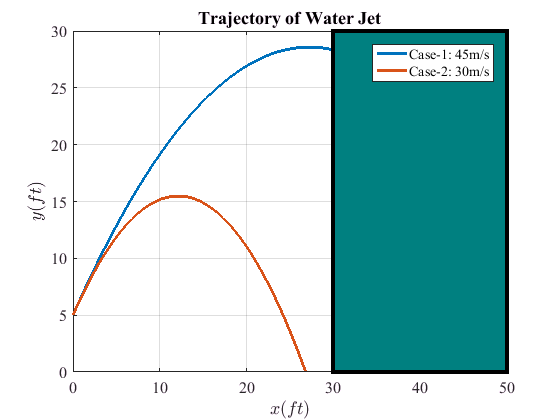


rectangle('Position',[xT,0,W,H],'FaceColor',[0 .5 .5],'EdgeColor','k',...
    'LineWidth',3)

## Assignment-2:

Consider the flow over a flat plate. Take suitable grid points and store data in those points according to the field equation given and then plot the x velocity(draw vector plot) variation in the direction perpendicular to the plate at x=0m 02m and 04m. Total length of the plate is 6m. It is known that x velocity variation along y direction is given by

$\frac{u}{U_{\infty } }=\frac{3}{2}\left(\frac{y}{\delta }\right)−\frac{1}{2}{\left(\frac{y}{\delta }\right)}^3$, where $\delta$=boundary layer thickness given by the relation $\delta =\frac{5x}{\sqrt{{Re}_x }}$ 

It is known that fluid flowing over the plate is SAE15W40 oil. 

$U_{\infty }$=1m/s, density=$850\frac{kg}{m^3 }$, dynamic viscosity=$0\ldotp 155Pa\ldotp s$

Also draw the locus of the boundary layer thickness along the plate length.